# Path plots of trajectory in RoVi

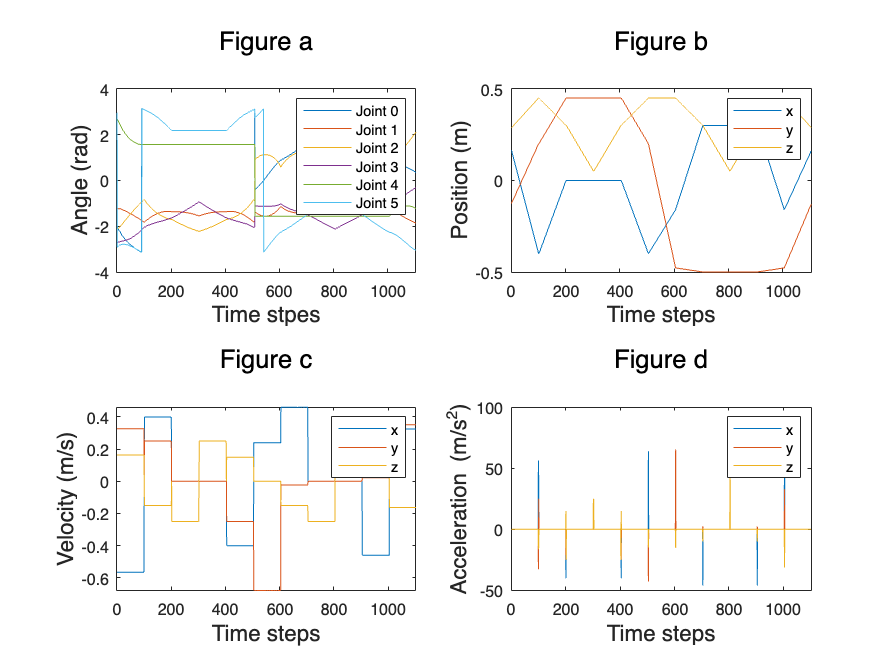

clear;
close all;

%% Import the data
% Import the joint angle data
joint_angle_data = importdata('experiment/P2P_Secondplace/JointsData.txt');
% Import the Cartesian position data
cartesian_position_data = importdata('experiment/P2P_Secondplace/TFData.txt');

num_nodes = size(joint_angle_data, 1);
joint_angle_data(1, 6) = joint_angle_data(1, 6) * -1;
positions = zeros(num_nodes, 3);
angles = zeros(num_nodes, 3);

for i = 1:num_nodes
    % Extract the current TF matrix
    start_index = 1 + (i - 1) * 4;
    end_index = 4 + (i - 1) * 4;
    tf_matrix = cartesian_position_data(start_index:end_index, 1:4);
    
    % Extract the x, y, and z positions
    positions(i, 1) = tf_matrix(1, 4);
    positions(i, 2) = tf_matrix(2, 4);
    positions(i, 3) = tf_matrix(3, 4);
    
    % Extract the rotation matrix and convert it to roll, pitch, yaw angles
    rotation_matrix = tf_matrix(1:3, 1:3);
    rpy_angles = rotm2eul(rotation_matrix);
    angles(i, 1) = rpy_angles(1);
    angles(i, 2) = rpy_angles(2);
    angles(i, 3) = rpy_angles(3);
    % Make sure the yaw angle is within a reasonable range
    if angles(i, 3) > 3
        angles(i, 3) = -3.142;
    end
end

%% Plot the joint angles
figure('Name', 'Joint angles');
h1 = subplot(2,2,1);
plot(joint_angle_data);
legend('Joint 0', 'Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5');
xlabel('Time stpes','FontSize',14);
ylabel('Angle (rad)','FontSize',14);
subtitle({'Figure a',''},'FontSize',16)

%% Plot the Cartesian positions
h2 = subplot(2,2,2);
plot(positions);
legend('x', 'y', 'z');
xlabel('Time steps','FontSize',14);
ylabel('Position (m)','FontSize',14);
subtitle({'Figure b',''},'FontSize',16)

%% Calculate and plot the linear velocities
h3 = subplot(2,2,3);
% Calculate the time step between steps (beacuse we run at a rate of 100 Hz)
time_step = 1 / 100;
% Calculate the linear velocity
linear_velocities = zeros(num_nodes - 1, 3);
for i = 1:num_nodes - 1
    linear_velocities(i, 1) = (positions(i + 1, 1) - positions(i, 1)) / time_step;
    linear_velocities(i, 2) = (positions(i + 1, 2) - positions(i, 2)) / time_step;
    linear_velocities(i, 3) = (positions(i + 1, 3) - positions(i, 3)) / time_step;
end
plot(linear_velocities);
legend('x', 'y', 'z');
xlabel({'Time steps',''},'FontSize',14);
ylabel('Velocity (m/s)','FontSize',14);
subtitle({'Figure c',''},'FontSize',16)

%% Calculate and plot the linear accelerations
h4 = subplot(2,2,4);
linear_accelerations = zeros(num_nodes - 2, 3);
for i = 1:num_nodes - 2
    linear_accelerations(i, 1) = (linear_velocities(i + 1, 1) - linear_velocities(i, 1)) / time_step;
    linear_accelerations(i, 2) = (linear_velocities(i + 1, 2) - linear_velocities(i, 2)) / time_step;
    linear_accelerations(i, 3) = (linear_velocities(i + 1, 3) - linear_velocities(i, 3)) / time_step;
end
plot(linear_accelerations);
legend('x', 'y', 'z');
xlabel('Time steps','FontSize',14);
ylabel('Acceleration (m/s^2)','FontSize',14);
subtitle({'Figure d',''},'FontSize',16)